%details of recording
load('mgh007m.mat')
sampling_fr = 360

sampling_fr = 360

sampling_interval = 1 / sampling_fr

sampling_interval = 0.0028

samples = size(val(7, :), 2)

samples = 21600

gain = 1000

gain = 1000

offset = 0

offset = 0

%creating time axis
X = [0 : sampling_interval : samples / sampling_fr - sampling_interval]

X =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


%Correcting signal (gain, offset)
data = val(7, :)

data =   -262   840   921   655   689   812   766   715   756   777   754   751   764   766   762   766   768   771   772   773   776   780   781   781   782   785   787   789   791   795   798   798   798   801   805   807   809   811   814   816   817   819   821   823   826   827   828   830   833   835


data = data - offset

data =   -262   840   921   655   689   812   766   715   756   777   754   751   764   766   762   766   768   771   772   773   776   780   781   781   782   785   787   789   791   795   798   798   798   801   805   807   809   811   814   816   817   819   821   823   826   827   828   830   833   835


data = data / gain

data =    -0.2620    0.8400    0.9210    0.6550    0.6890    0.8120    0.7660    0.7150    0.7560    0.7770    0.7540    0.7510    0.7640    0.7660    0.7620    0.7660    0.7680    0.7710    0.7720    0.7730    0.7760    0.7800    0.7810    0.7810    0.7820    0.7850    0.7870    0.7890    0.7910    0.7950    0.7980    0.7980    0.7980    0.8010    0.8050    0.8070    0.8090    0.8110    0.8140    0.8160    0.8170    0.8190    0.8210    0.8230    0.8260    0.8270    0.8280    0.8300    0.8330    0.8350


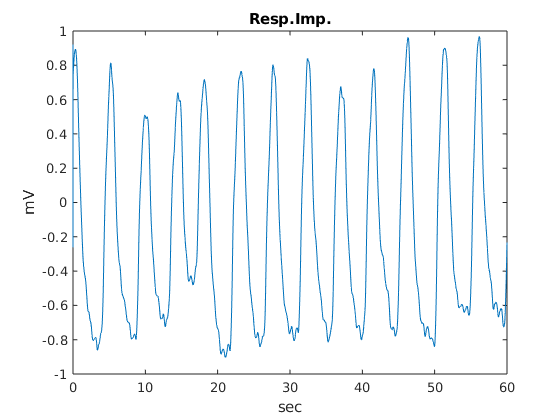

%plot
figure
plot(X, data)
title('Resp.Imp.')
xlim([0, 60])
xlabel('sec')
ylabel('mV')

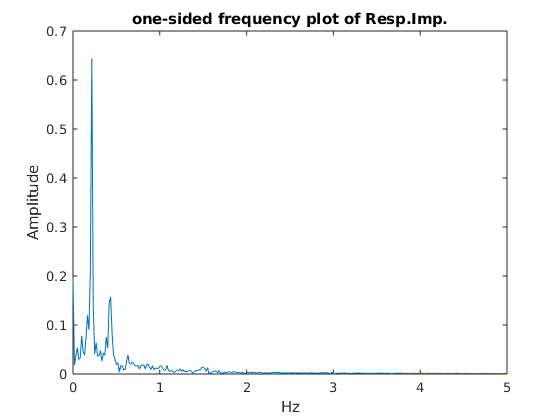

figure
Y = fft(data);
P2 = abs(Y/samples);
P1 = P2(1:samples/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = sampling_fr*(0:(samples/2))/samples;
plot(f, P1)
title('one-sided frequency plot of Resp.Imp.')
xlabel('Hz')
ylabel('Amplitude')
xlim([0 5])

%define carrier signal
fr_of_carr = 100

fr_of_carr = 100

phi = 0

phi = 0

C = 1

C = 1

carr_sig_value = C * sin(2*pi*fr_of_carr*X+phi)

carr_sig_value =          0    0.9848   -0.3420   -0.8660    0.6428    0.6428   -0.8660   -0.3420    0.9848   -0.0000   -0.9848    0.3420    0.8660   -0.6428   -0.6428    0.8660    0.3420   -0.9848    0.0000    0.9848   -0.3420   -0.8660    0.6428    0.6428   -0.8660   -0.3420    0.9848   -0.0000   -0.9848    0.3420    0.8660   -0.6428   -0.6428    0.8660    0.3420   -0.9848    0.0000    0.9848   -0.3420   -0.8660    0.6428    0.6428   -0.8660   -0.3420    0.9848   -0.0000   -0.9848    0.3420    0.8660   -0.6428


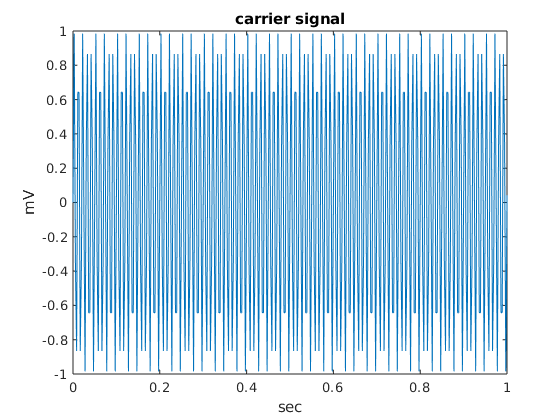

figure
plot(X, carr_sig_value)
title('carrier signal')
xlabel('sec')
ylabel('mV')
xlim([0,1])

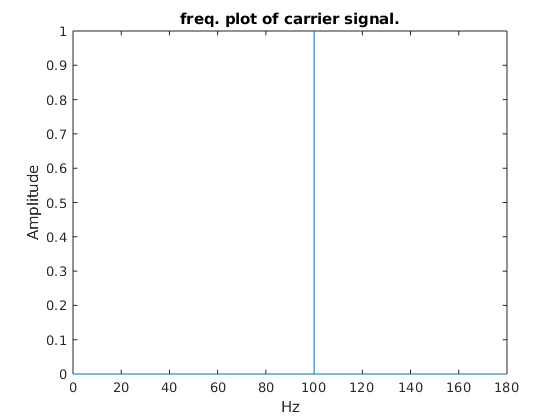

%spectrum of carrier signal:
figure
Y = fft(carr_sig_value);
P2 = abs(Y/samples);
P1 = P2(1:samples/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = sampling_fr*(0:(samples/2))/samples;
plot(f, P1)
title('freq. plot of carrier signal.')
xlabel('Hz')
ylabel('Amplitude')

%xlim([0 10])

%calculating modulated signal: m_left(t)
modulated_signal = (1 + data) .* carr_sig_value

modulated_signal =          0    1.8120   -0.6570   -1.4333    1.0857    1.1647   -1.5294   -0.5866    1.7293   -0.0000   -1.7274    0.5989    1.5277   -1.1352   -1.1326    1.5294    0.6047   -1.7441    0.0000    1.7461   -0.6074   -1.5415    1.1448    1.1448   -1.5433   -0.6105    1.7599   -0.0000   -1.7638    0.6139    1.5571   -1.1557   -1.1557    1.5597    0.6173   -1.7795    0.0000    1.7835   -0.6204   -1.5727    1.1679    1.1692   -1.5770   -0.6235    1.7983   -0.0000   -1.8002    0.6259    1.5874   -1.1795


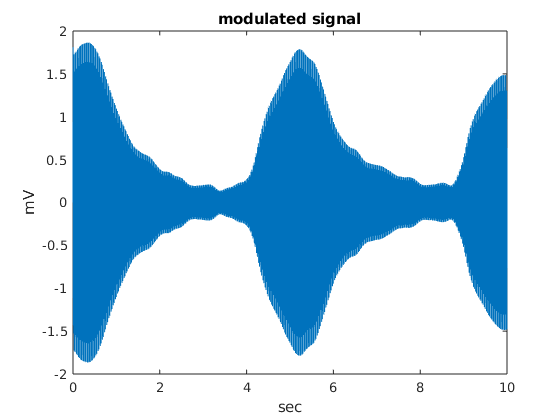

figure
plot(X, modulated_signal)
xlim([0 10])
title('modulated signal')
xlabel('sec')
ylabel('mV')

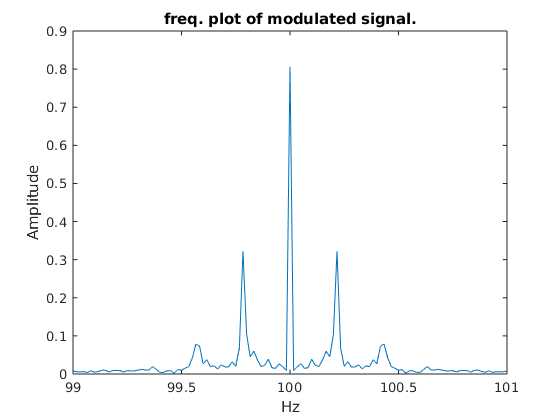

%spectrum of modulated signal
figure
Y = fft(modulated_signal);
P2 = abs(Y/samples);
P1 = P2(1:samples/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = sampling_fr*(0:(samples/2))/samples;
plot(f, P1)
title('freq. plot of modulated signal.')
xlabel('Hz')
ylabel('Amplitude')
xlim([99 101])

%subplots
figure
subplot(3, 2, 1)
plot(X, data)
title('Resp.Imp.')
xlim([0, 60])
xlabel('sec')
ylabel('mV')
xlim([0 10])


subplot(3, 2, 2)
Y = fft(data);
P2 = abs(Y/samples);
P1 = P2(1:samples/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = sampling_fr*(0:(samples/2))/samples;
plot(f, P1)
title('one-sided frequency plot of Resp.Imp.')
xlabel('Hz')
ylabel('Amplitude')
xlim([0 2])



subplot(3,2,3)
fr_of_carr = 100

fr_of_carr = 100

phi = 0

phi = 0

C = 1

C = 1

carr_sig_value = C * sin(2*pi*fr_of_carr*X+phi)

carr_sig_value =          0    0.9848   -0.3420   -0.8660    0.6428    0.6428   -0.8660   -0.3420    0.9848   -0.0000   -0.9848    0.3420    0.8660   -0.6428   -0.6428    0.8660    0.3420   -0.9848    0.0000    0.9848   -0.3420   -0.8660    0.6428    0.6428   -0.8660   -0.3420    0.9848   -0.0000   -0.9848    0.3420    0.8660   -0.6428   -0.6428    0.8660    0.3420   -0.9848    0.0000    0.9848   -0.3420   -0.8660    0.6428    0.6428   -0.8660   -0.3420    0.9848   -0.0000   -0.9848    0.3420    0.8660   -0.6428


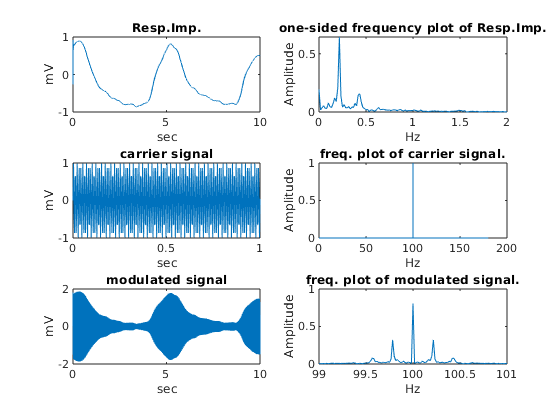

plot(X, carr_sig_value)
title('carrier signal')
xlabel('sec')
ylabel('mV')
xlim([0,1])



subplot(3,2,4)
Y = fft(carr_sig_value);
P2 = abs(Y/samples);
P1 = P2(1:samples/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = sampling_fr*(0:(samples/2))/samples;
plot(f, P1)
title('freq. plot of carrier signal.')
xlabel('Hz')
ylabel('Amplitude')



subplot(3,2,5)
plot(X, modulated_signal)
xlim([0 10])
title('modulated signal')
xlabel('sec')
ylabel('mV')



subplot(3,2,6)
Y = fft(modulated_signal);
P2 = abs(Y/samples);
P1 = P2(1:samples/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = sampling_fr*(0:(samples/2))/samples;
plot(f, P1)
title('freq. plot of modulated signal.')
xlabel('Hz')
ylabel('Amplitude')
xlim([99 101])